# Stima OLS: altri modelli

clear, rng('default')

## Creazione di istanti di tempo equispaziati nell'intervallo [0; Td[

% Dati
% N = 100; % numero di campioni (o di istanti)
% Td = 5; % durata dell'osservazione

% Domande
% Ts % periodo di campionamento
% n % vettore colonna degli indici dei campioni
% t % vettore colonna degli istanti di tempo (istanti di campionamento)

% Codice iniziale
N = 100; % numero di campioni (o di istanti)
Td = 5; % durata dell'osservazione

### Soluzione

Ts = Td/N 

Ts = 0.0500

n = (0:N-1)'

n =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


t = n*Ts

t =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500


## Creazione di errori di misura in ingresso omoschedastici, i.i.d. con distribuzione uniforme

% Dati
% U0 = 2 % scalare, incertezza di caso peggiore in ingresso

% Domande
% U % vettore delle incertezze di caso peggiore
% e % vettore colonna degli errori
% u0 % incertezza standard in ingresso
% u % vettore delle incertezze standard in ingresso
% R % matrice dei coefficienti di correlazione degli errori in ingresso
% Sigma % matrice covarianza degli errori in ingresso

% Codice iniziale
U0 = 2

U0 = 2

### Soluzione

U = U0*ones(N,1)

U =      2
     2
     2
     2
     2
     2
     2
     2
     2
     2


e = unifrnd(-U0,U0,[N,1])

e =     1.2589
    1.6232
   -1.4921
    1.6535
    0.5294
   -1.6098
   -0.8860
    0.1875
    1.8300
    1.8596


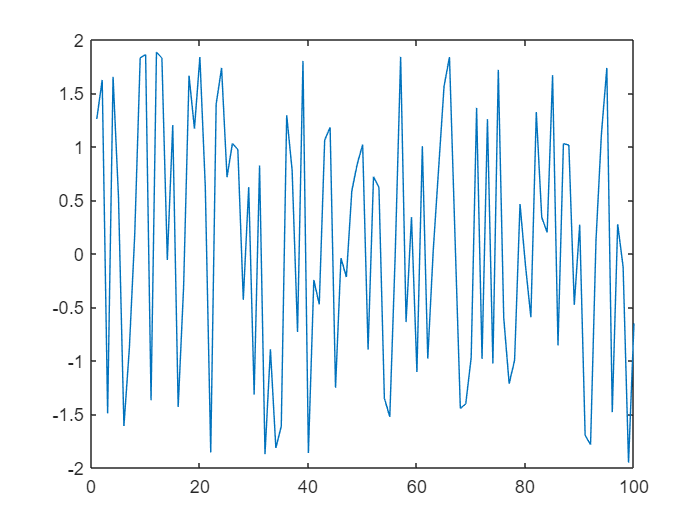

plot(e)

u0 = U0/sqrt(3)

u0 = 1.1547

u = U/sqrt(3)

u =     1.1547
    1.1547
    1.1547
    1.1547
    1.1547
    1.1547
    1.1547
    1.1547
    1.1547
    1.1547


u = u0*ones(N,1) % altenativa

u =     1.1547
    1.1547
    1.1547
    1.1547
    1.1547
    1.1547
    1.1547
    1.1547
    1.1547
    1.1547


R = eye(N)

R =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0   

% hh = plot(R(1,:)); ylim([0,1]); xlim([1,100]);
% for i = 1:N
%     hh.YData = R(i,:);
%     pause(0.1)
% end

Sigma = diag(u)*R*diag(u) % formula generale

Sigma =     1.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

Sigma = diag(u)^2 % formula per errori incorrelati

Sigma =     1.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

Sigma = u0^2*eye(N) % formula per errori omoschedastici

Sigma =     1.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

## Stima OLS di parametri e segnale 

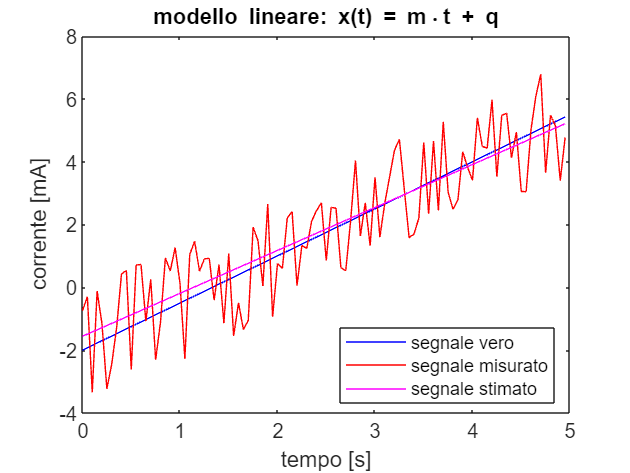

% Costruire anche una tabella e un grafico come in figura (che si riferiscono a un modello lineare)

% Dati
% e % vettore degli errori
% Sono dati i parametri veri del segnale. I casi selezionabili sono i seguenti:
% === modello = 1; theta = [m; q] === modello lineare x = m*t+q
% === modello = 2; theta = [v0; a] === modello parabolico x = v0*t+1/2*a*t^2
% === modello = 3; theta = [a0; a1; a2; a3] === modello polinomiale x = a0 + a1*t + a2*t^2 + a3*t^3
% === modello = 4; theta = [c0; a; b] === modello sinusoidale x = c0 + a*cos(w*t) - b*sin(w*t) = c0 + d*cos(w*t)
modello = 2

modello = 2


% Domande
% theta % vettore dei parametri
% A % matrice delle funzioni base
% x % segnale vero
% y % segnale misurato
% Q % matrice gramiana inversa delle colonne di A
% C % matrice pseudoinversa sinistra di A
% P % matrice proiezione
% theta_hat % stima dei parametri sulla base di y
% x_hat % stima del segnale sulla base di y

% Codice iniziale
switch modello
    case 1
        titolo = 'modello lineare: x(t) = {m}\cdot{t} + q';
        m = 1.5; q = -2; % parametri del segnale
        theta = [m; q]
        fprintf('theta = [m; q]')
        fprintf('x = m*t+q')
        nomi_parametri = {'m','q'};
        nome_segnale = 'corrente [mA]';
    case 2
        titolo = 'modello parabolico: x(t) = v0\cdott + 1/2\cdot{a}\cdot{t^2}';
        v0 = 1; a = -1; % parametri del segnale (velocità iniziale, accelerazione)
        theta = [v0; a];
        fprintf('theta = [v0; a]')
        fprintf('x = v0*t+1/2*a*t^2')
        nomi_parametri = {'v0','a'};
        nome_segnale = 'posizione [m]';
    case 3
        titolo = 'modello polinomiale: x(t) = a_0 + {a_1}t + {a_2}t^2 + {a_3}t^3';
        a0 = -1; a1 = 1.5; a2 = 2; a3 = -0.5; % parametri del segnale;
        theta = [a0; a1; a2; a3]
        fprintf('theta = [a0; a1; a2; a3]')
        fprintf('x = a0 + a1*t + a2*t^2 + a3*t^3')
        nomi_parametri = {'a_0','a_1','a_2','a_3'};
        nome_segnale = 'temperatura [°C]';
    case 4
        titolo = 'modello sinusoidale: x(t) = c_0 + d cos(\omega t + \phi)'
        c0 = -0.5; d = 2; phi = -pi/3; % parametri non lineari del segnale
        a = d*cos(phi); b = d*sin(phi); % parametri lineari del segnale
        theta = [c0; a; b]
        fprintf('theta = [c0; a; b]')
        fprintf('x = c0 + a*cos(w*t) - b*sin(w*t)')
        nomi_parametri = {'c_0','a','b'}
        nome_segnale = 'tensione [V]'
        Np = 1.5;
        Tx = Td/Np;
        fx = 1/Tx;
        w = 2*pi*fx;
end

theta = [v0; a]

x = v0*t+1/2*a*t^2

### Soluzione

#### Vettore theta e matrice A

A = [t, t.^2/2]

A =          0         0
    0.0500    0.0013
    0.1000    0.0050
    0.1500    0.0113
    0.2000    0.0200
    0.2500    0.0312
    0.3000    0.0450
    0.3500    0.0613
    0.4000    0.0800
    0.4500    0.1013


#### Valori veri e misurati

x = A*theta

x =          0
    0.0488
    0.0950
    0.1388
    0.1800
    0.2188
    0.2550
    0.2888
    0.3200
    0.3488


y = x + e

y =     1.2589
    1.6719
   -1.3971
    1.7923
    0.7094
   -1.3911
   -0.6310
    0.4763
    2.1500
    2.2083


#### Matrici del metodo OLS

Q = (A'*A)^-1

Q =     0.0195   -0.0098
   -0.0098    0.0053


C = Q*A'

C =          0    0.0010    0.0019    0.0028    0.0037    0.0046    0.0054    0.0062    0.0070    0.0078    0.0085    0.0092    0.0099    0.0106    0.0112    0.0119    0.0125    0.0130    0.0136    0.0141    0.0146    0.0151    0.0155    0.0159    0.0163    0.0167    0.0171    0.0174    0.0177    0.0180    0.0182    0.0184    0.0187    0.0188    0.0190    0.0191    0.0192    0.0193    0.0194    0.0194    0.0194    0.0194    0.0193    0.0193    0.0192    0.0191    0.0189    0.0188    0.0186    0.0184
         0   -0.0005   -0.0010   -0.0014   -0.0019   -0.0023   -0.0027   -0.0031   -0.0035   -0.0039   -0.0042   -0.0046   -0.0049   -0.0053   -0.0056   -0.0059   -0.0062   -0.0064   -0.0067   -0.0069   -0.0072   -0.0074   -0.0076   -0.0078   -0.0080   -0.0081   -0.0083   -0.0084   -0.0086   -0.0087   -0.0088   -0.0089   -0.0090   -0.0090   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0091   -0.0090   -0.0090   -0.0089   -0.0088   -0.0087   -0.0086   -0.0085   -0.0084   -0

P = A*C

P =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0

#### Stima parametri

theta_hat = C*y

theta_hat =     1.1735
   -1.0930


table(theta,theta_hat,'RowNames',nomi_parametri)

ans = 2×2 table
          theta    theta_hat
          _____    _________

    v0      1       1.1735  
    a      -1       -1.093  


#### Stima segnale

x_hat = P*y

x_hat =          0
    0.0573
    0.1119
    0.1637
    0.2128
    0.2592
    0.3029
    0.3438
    0.3820
    0.4174


x_hat = A*theta_hat

x_hat =          0
    0.0573
    0.1119
    0.1637
    0.2128
    0.2592
    0.3029
    0.3438
    0.3820
    0.4174


#### Grafico stima

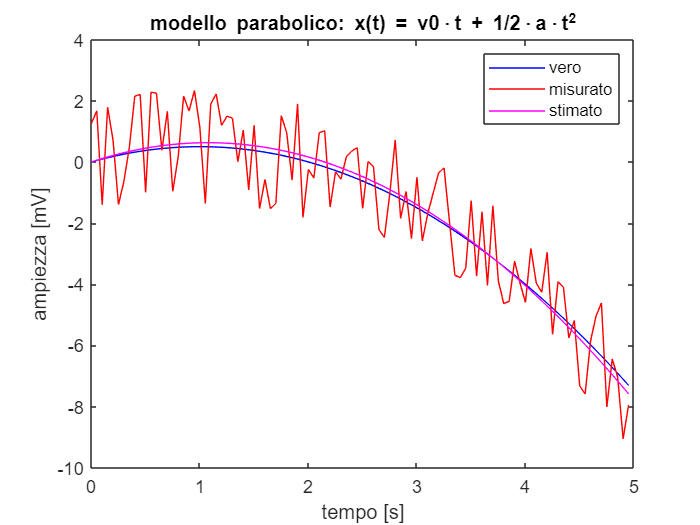

plot(t,x,'b',t,y,'r',t,x_hat,'m')
xlabel('tempo [s]')
ylabel('ampiezza [mV]')
title(titolo)
legend('vero','misurato','stimato')

## Valutazione di tipo B dell'incertezza sui parametri stimati

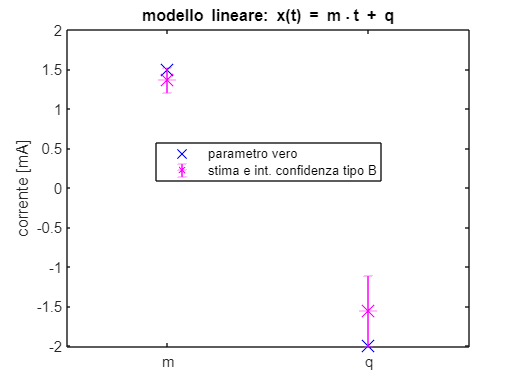

% Produrre anche un grafico come quello in figura

% Dati
% Quelli del quesito precedente
% cp % probabilità di copertura

% Domande
% Sigma_theta = matrice covarianza parametri stimati
% u_theta % vettore colonna incertezze standard parametri stimati
% kcp % fattore di copertura di tipo B
% Ucp_theta % vettore colonna incertezze estese di tipo B
% U_theta % vettore colonna incertezze di caso peggiore (di tipo B)
% kmax % fattore di copertura max - per verifica incertezze estese
% theta_L % limite "lower" dell'intervallo di confidenza
% theta_U % % limite "upper" dell'intervallo di confidenza

% Codice iniziale
cp = 0.95

cp = 0.9500

### Soluzione

#### Matrice covarianza in uscita, formula per errori omoschedastici

Sigma_theta = u0^2*Q

Sigma_theta =     0.0260   -0.0131
   -0.0131    0.0070


#### Matrice covarianza in uscita, formula generale 

Sigma_theta = C*Sigma*C'

Sigma_theta =     0.0260   -0.0131
   -0.0131    0.0070


#### Incertezze standard parametri

u_theta = sqrt(diag(Sigma_theta))

u_theta =     0.1612
    0.0837


#### Fattore di copertura di tipo B

kcp = norminv((1+cp)/2)

kcp = 1.9600

#### Incertezze estese parametri

Ucp_theta = u_theta*kcp

Ucp_theta =     0.3160
    0.1640


#### Incertezze di caso peggiore e fattore di copertura massimo

U_theta = abs(C)*U

U_theta =     2.5088
    1.2796


kmax = U_theta./u_theta

kmax =    15.5612
   15.2926


#### Intervalli di confidenza per i parametri

theta_L = theta_hat - Ucp_theta

theta_L =     0.8575
   -1.2570


theta_U = theta_hat + Ucp_theta

theta_U =     1.4895
   -0.9290


#### Grafico intervalli di confidenza

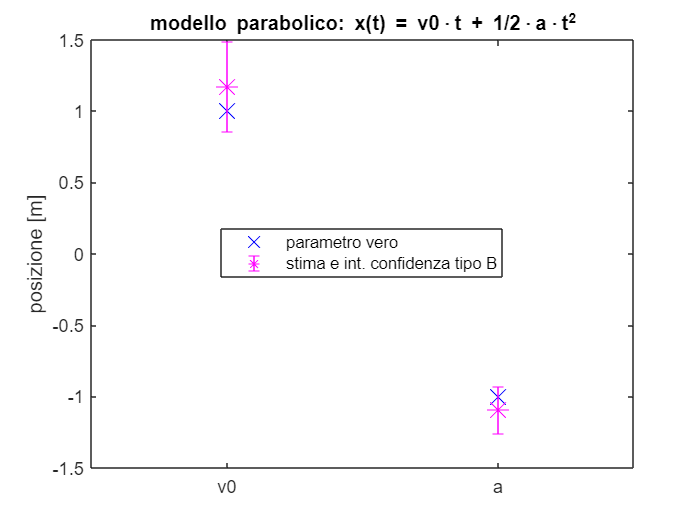

plot(theta,'bx','MarkerSize',12), hold on
errorbar(theta_hat,Ucp_theta,'m*','MarkerSize',12), hold off
ylabel(nome_segnale)
title(titolo)

xticks(1:numel(theta_hat))
xticklabels(nomi_parametri)
legend('parametro vero','stima e int. confidenza tipo B','Location','best')

xlim([0.5,numel(theta_hat)+0.5])

## Valutazione di tipo A dell'incertezza sui parametri stimati

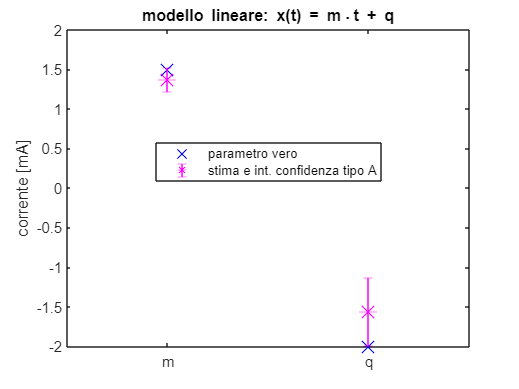

% Produrre anche un grafico come quello in figura

% Dati
% Quelli del quesito precedente
% cp % probabilità di copertura

% Domande
% e_hat % residuo
% nu % numero di g.d.l. del residuo
% u0_A % valutazione tipo A dell'incertezza in ingresso
% Sigma_theta_A = matrice covarianza parametri stimati
% u_theta_A % vettore colonna incertezze standard parametri stimati
% Ucp_theta_A % vettore colonna incertezze estese di tipo Aze estese
% theta_L_A % limite "lower" dell'intervallo di confidenza
% theta_U_A % % limite "upper" dell'intervallo di confidenza

% Codice iniziale
cp = 0.95

cp = 0.9500

### Soluzione

#### Residuo

e_hat= y - x_hat

e_hat =     1.2589
    1.6146
   -1.5089
    1.6285
    0.4966
   -1.6503
   -0.9339
    0.1325
    1.7681
    1.7909


#### Numero di g.d.l. del residuo

N_theta = size(A,2)

N_theta = 2

nu = N-N_theta

nu = 98

#### Incertezza standard in ingresso

SSR = sum(e_hat.^2)

SSR = 139.3460

u0_A = sqrt(SSR/nu)

u0_A = 1.1924


fprintf('u0 = %g', u0) % per confronto

u0 = 1.1547

#### Matrice covarianza parametri, formula per errori omoschedastici

Facciamo la valutazione tipo A nel solo caso di errori omoschedastici

Sigma_theta_A = u0_A^2*Q

Sigma_theta_A =     0.0277   -0.0139
   -0.0139    0.0075


#### Incertezze standard parametri

u_theta_A = sqrt(diag(Sigma_theta_A))

u_theta_A =     0.1665
    0.0864



fprintf('u_theta = \n') % per confronto

u_theta = 


fprintf('%g\n', u_theta)

0.16122
0.0836744


#### Fattore di copertura di tipo A

kcp_A = tinv((1+cp)/2,nu)

kcp_A = 1.9845

#### Incertezza estesa parametri

Ucp_theta_A = u_theta_A*kcp_A

Ucp_theta_A =     0.3304
    0.1715


#### Intervalli di confidenza per i parametri

theta_L_A = theta_hat - Ucp_theta_A

theta_L_A =     0.8431
   -1.2645


theta_U_A = theta_hat + Ucp_theta_A

theta_U_A =     1.5039
   -0.9215


#### Grafico intervalli di confidenza

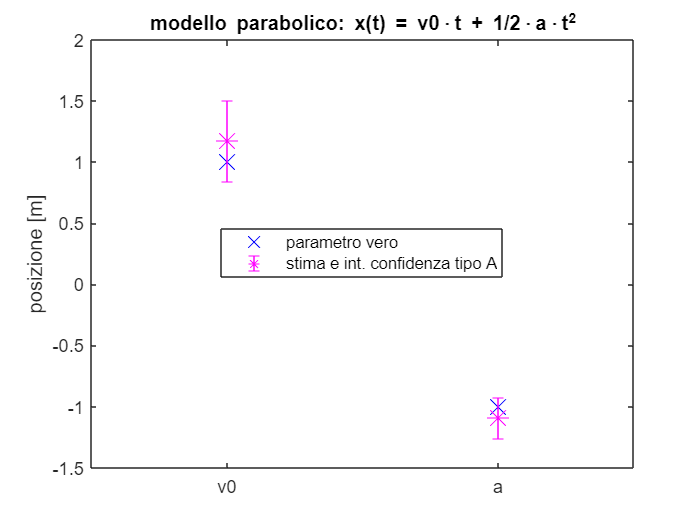

plot(theta,'bx','MarkerSize',12), hold on
errorbar(theta_hat,Ucp_theta_A,'m*','MarkerSize',12), hold off
ylabel(nome_segnale)
title(titolo)

xticks(1:numel(theta_hat))
xticklabels(nomi_parametri)
legend('parametro vero','stima e int. confidenza tipo A','Location','best')

xlim([0.5,numel(theta_hat)+0.5])

## Valutazione di tipo B dell'incertezza sul segnale stimato

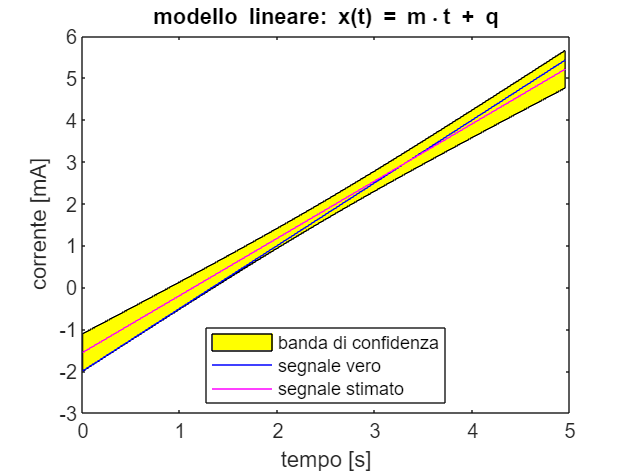

% Produrre anche un grafico come quello in figura

% Dati
% Quelli del quesito precedente

% Domande
% Sigma_x % matrice covarianza di x_hat
% u_x % vettore colonna incertezze standard segnale stimato
% R_x % matrice coefficienti di correlazione errori sul segnale stimato
% Ucp_x = % vettore colonna incertezze estese
% x_U % limite "lower" della banda di confidenza
% x_L % limite "upper" della banda di confidenza

### Soluzione

#### Matrice covarianza, formula per errori omoschedastici

Sigma_x = u0^2*P

Sigma_x =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0011    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.001

#### Matrice covarianza, formula generale 

Sigma_x = P*Sigma*P'

Sigma_x =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0011    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0012    0.0012    0.001

#### Incertezza segnale

u_x = sqrt(diag(Sigma_x))

u_x =          0
    0.0080
    0.0157
    0.0233
    0.0306
    0.0378
    0.0447
    0.0515
    0.0580
    0.0644


Ucp_x = u_x*kcp

Ucp_x =          0
    0.0156
    0.0308
    0.0456
    0.0600
    0.0740
    0.0877
    0.1009
    0.1137
    0.1262


#### Matrice dei coefficienti di correlazione

R_x = diag(u_x)^-1*Sigma_x*diag(u_x)^-1

R_x =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN 

% hh = plot(R_x(1,:)); ylim([0,1]); xlim([1,100]);
% for i = 1:N
%     hh.YData = R_x(i,:);
%     pause(0.1)
% end

#### Banda di confidenza per il segnale

x_U = x_hat + Ucp_x

x_U =          0
    0.0729
    0.1427
    0.2093
    0.2729
    0.3333
    0.3905
    0.4447
    0.4957
    0.5436


x_L = x_hat - Ucp_x

x_L =          0
    0.0417
    0.0811
    0.1181
    0.1528
    0.1852
    0.2152
    0.2429
    0.2682
    0.2912


#### Grafico banda di confidenza

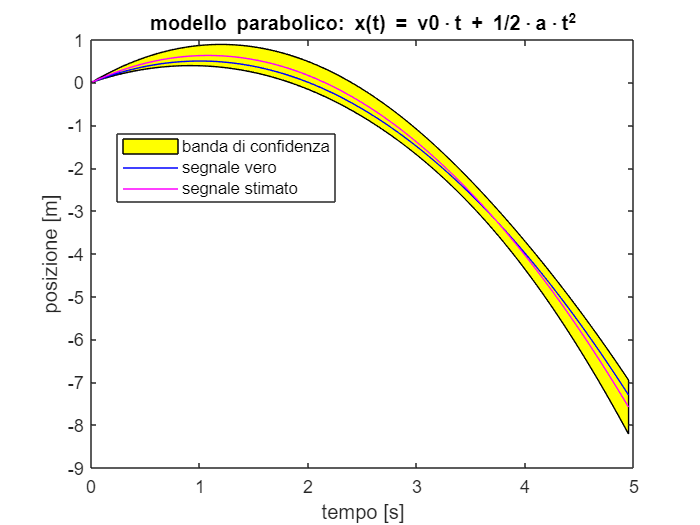

fill([t', fliplr(t')], [x_L', fliplr(x_U')], 'y')
hold on
plot(t,x,'b',t,x_hat,'m')
hold off
xlabel('tempo [s]')
ylabel(nome_segnale)
title(titolo)
legend('banda di confidenza','segnale vero','segnale stimato','Location','best')